# 1.1.14 Решение СЛАУ. Реализация метода наименьших квадратов 

## Постановка задачи

Метод наименьших квадратов (МНК, англ. ***Ordinary Least Squares, OLS*****)** — математический метод, применяемый для решения различных задач, основанный на минимизации суммы квадратов отклонений некоторых функций от искомых переменных. Он является одним из базовых методов регрессионного анализа для приближенного решения переопределенных систем, т. е[.](https://en.wikipedia.org/wiki/Overdetermined_system) систем уравнений, в которых уравнений больше, чем неизвестных. «Наименьшие квадраты» означают, что общее решение минимизирует сумму квадратов отклонений, полученных в результате решения каждого отдельного уравнения.

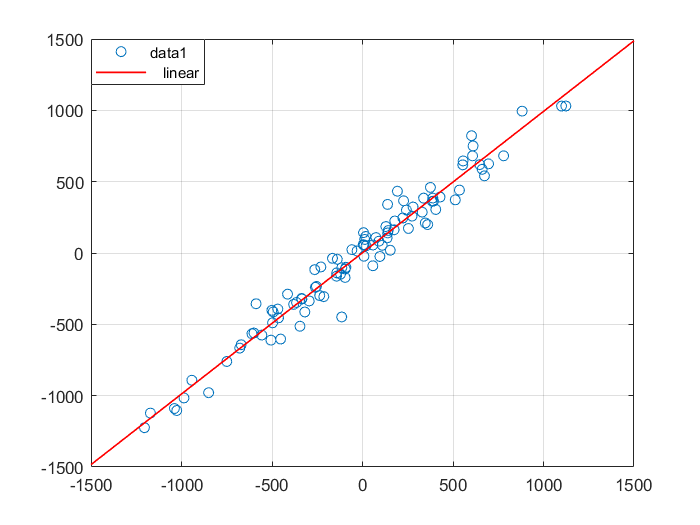

В частности, метод наименьших квадратов может использоваться для решения системы линейных уравнений , где *A* - прямоугольная матрица размера  (т.е. число строк матрицы *A* больше количества искомых переменных). Такая система уравнений может описывать поведение объекта, где *A*- это входные воздействия на объект, *x* - вектор независимых переменных, которые описывают внутренние состояния системы, *b* - вектор выходных данных объекта.

Такая система уравнений в общем случае не имеет решения. Поэтому эту систему можно «решить» только в смысле выбора такого вектора *x*, который минимизирует «расстояние» между векторами  и *b*. Для этого можно применить критерий минимизации суммы квадратов разностей левой и правой частей уравнений системы, то есть . 

Нетрудно показать, что решение этой задачи минимизации приводит к решению следующей системы уравнений:

.

## Задание:

Есть объект описываемый следующей моделью: .

Наша задача - определить параметры этой модели (в данном случае это ).

Для этого проведем эксперимент на объекте - 100 измерений, и в результате эксперимента получим зашумленные данные.

Найдите решение системы уравнений.

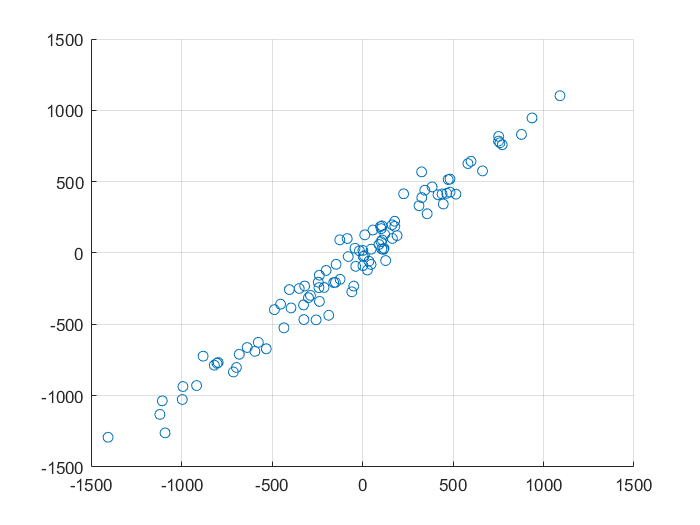

% Смоделируем эксперимент - 100 измерений:
% Входные воздействия, как случайные воздействия с нормальным распределением:

% x, это те параметры которые будем оценивать. Мы их не знаем, но для получения данных эксперимента зададимся значениями, например такими:

% Выходные данные тоже немного зашумлены из-за погрешности датчика:


% Теперь у нас есть данные 100 экспериментов в виде матрицы A и вектора b. Нужно найти x.
% Cистема Ax=b несоместна, т.е. не имеет решений. Пока мы не будем это доказывать, примем как данность.
% Можем посмотреть на результаты эксперимента:


% Найдите решение несовместной системы с помощью метода наименьших квадратов:
